load('AnalogData.mat');
rawData = out.AnalogData

rawData =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Nround = 21;
Nsample = 2001;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 2)

analogs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0     


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


meanVoltDataVSRef = ((mean(voltData, 2)/3.3) *100)

meanVoltDataVSRef =          0
         0
    1.0438
    8.2973
   13.2379
   18.1540
   23.4308
   28.9958
   34.0876
   39.5890


measureX = 0 : 5 : 100

measureX =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


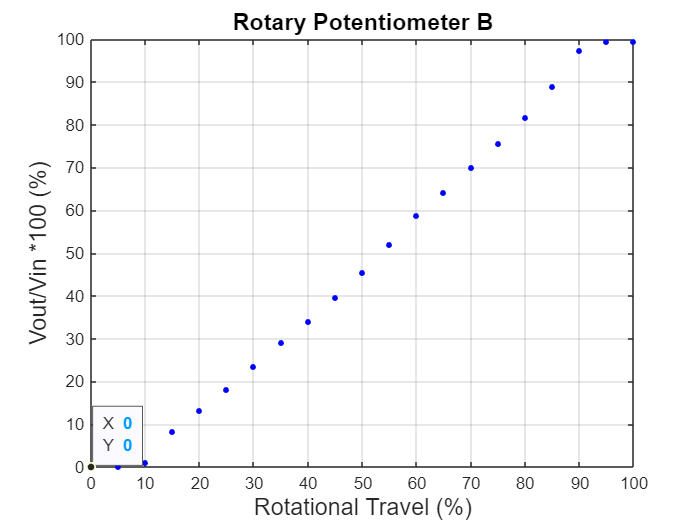

% Plotting
measureGraph = plot(measureX, meanVoltDataVSRef, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% Add on
datatip(measureGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Rotary Potentiometer B', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin *100 (%)', 'FontSize', 14); 

% Load PlotData
load('rotaryB.mat');
load('x.mat');

% Read and plot datasheet
datasheetValue = rotaryB

datasheetValue =     0.0700    0.1300    5.3500   10.8900   16.3000   22.1000   27.4800   33.4900   38.8700   44.7900   50.0600   55.1500   61.2700   66.2900   72.3000   77.4600   84.0100   88.8400   94.9000   99.9200   99.8900


datasheetX = x;

% Calculate Errors
err = 20/100 * datasheetValue

err =     0.0140    0.0260    1.0700    2.1780    3.2600    4.4200    5.4960    6.6980    7.7740    8.9580   10.0120   11.0300   12.2540   13.2580   14.4600   15.4920   16.8020   17.7680   18.9800   19.9840   19.9780


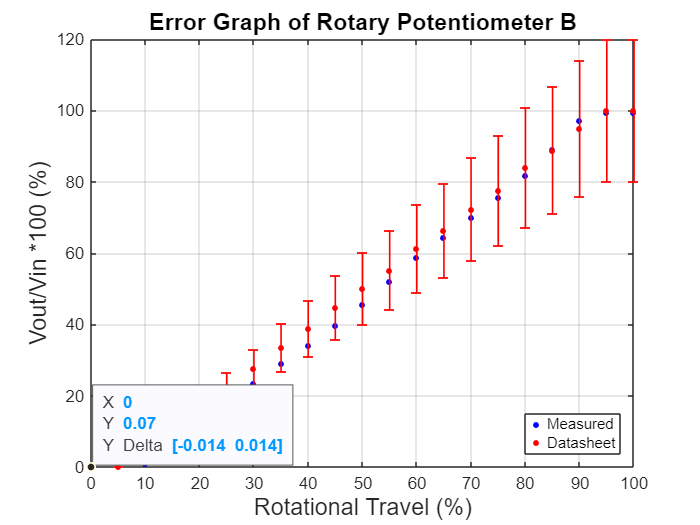

% Plotting Graph
measureGraph;
hold on;
datasheetGraph = plot(datasheetX, datasheetValue, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
errorGraph = errorbar(measureX, datasheetValue, err, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
datatip(measureGraph);
datatip(datasheetGraph);
datatip(errorGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Error Graph of Rotary Potentiometer B', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin *100 (%)', 'FontSize', 14); 
legend('Measured', 'Datasheet', 'Location', 'southeast');